clc;
clear all; close all;

P = tf([100],[1 0])     % 100/s


P =
 
  100
  ---
   s
 
Continuous-time transfer function.



C = tf([100],[1 40])    % 100/(s+40)


C =
 
   100
  ------
  s + 40
 
Continuous-time transfer function.



## Prob 3a. Bode Plot

disp('>> Prob 3a. Bode Plot of the Loop Transfer Function');

>> Prob 3a. Bode Plot of the Loop Transfer Function



L = P*C


L =
 
    10000
  ----------
  s^2 + 40 s
 
Continuous-time transfer function.



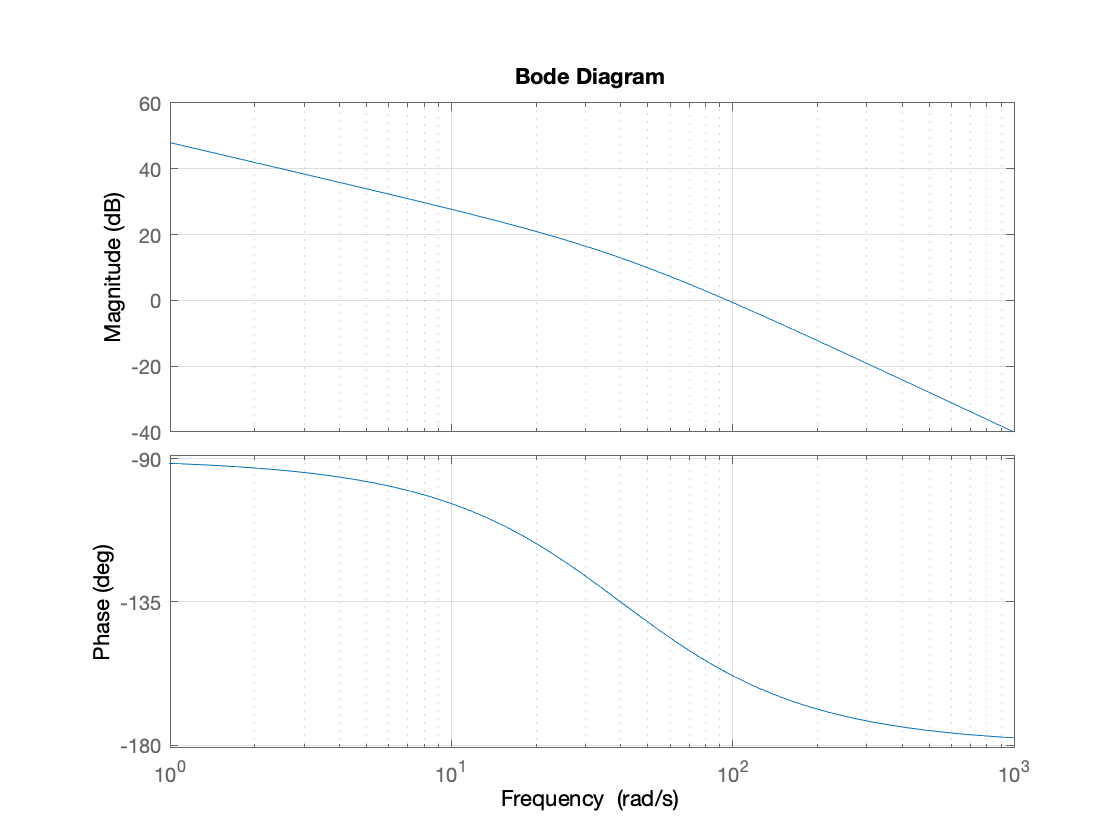


figure(1)
bode(L); grid on;


disp(repmat('=',1,80));

## Prob 3b. Gain and Phase Margins

disp('>> Prob 3b. G.M. & P.M.');

>> Prob 3b. G.M. & P.M.



[GM, PM] = margin(L)

GM = Inf

PM = 22.6028


disp(repmat('=',1,80));

## Prob 3c. Nyquist Plot

disp('>> Prob 3c. Nyquist Plot');

>> Prob 3c. Nyquist Plot


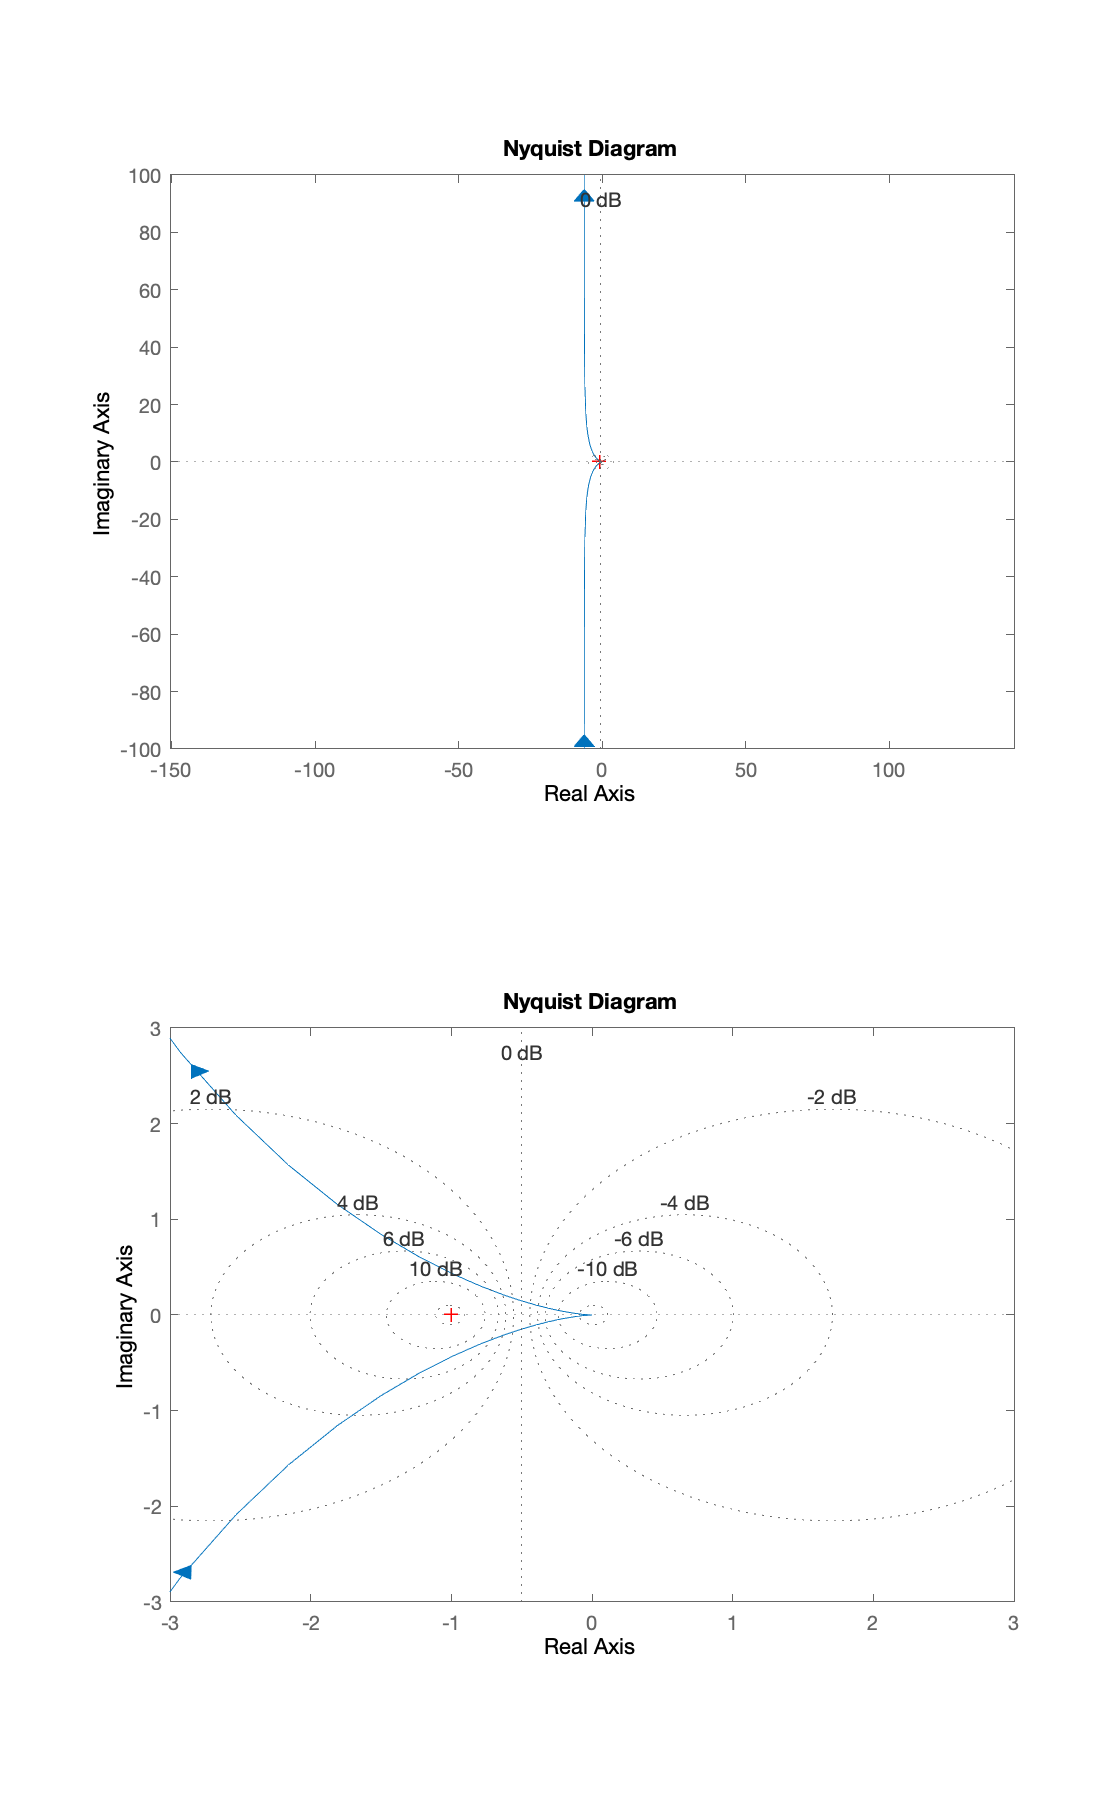


figure(2)
set(gcf, 'position', [0, 0, 560, 900])
subplot(2,1,1)
nyquist(L); grid on; axis equal;
subplot(2,1,2)
nyquist(L); grid on; axis([-3 3 -3 3]);


disp(repmat('=',1,80));

## Prob 3d. Closed-loop System

disp('>> Prob 3d. Closed-loop System');

>> Prob 3d. Closed-loop System



T = L/(1+L)


T =
 
         10000 s^2 + 400000 s
  -----------------------------------
  s^4 + 80 s^3 + 11600 s^2 + 400000 s
 
Continuous-time transfer function.



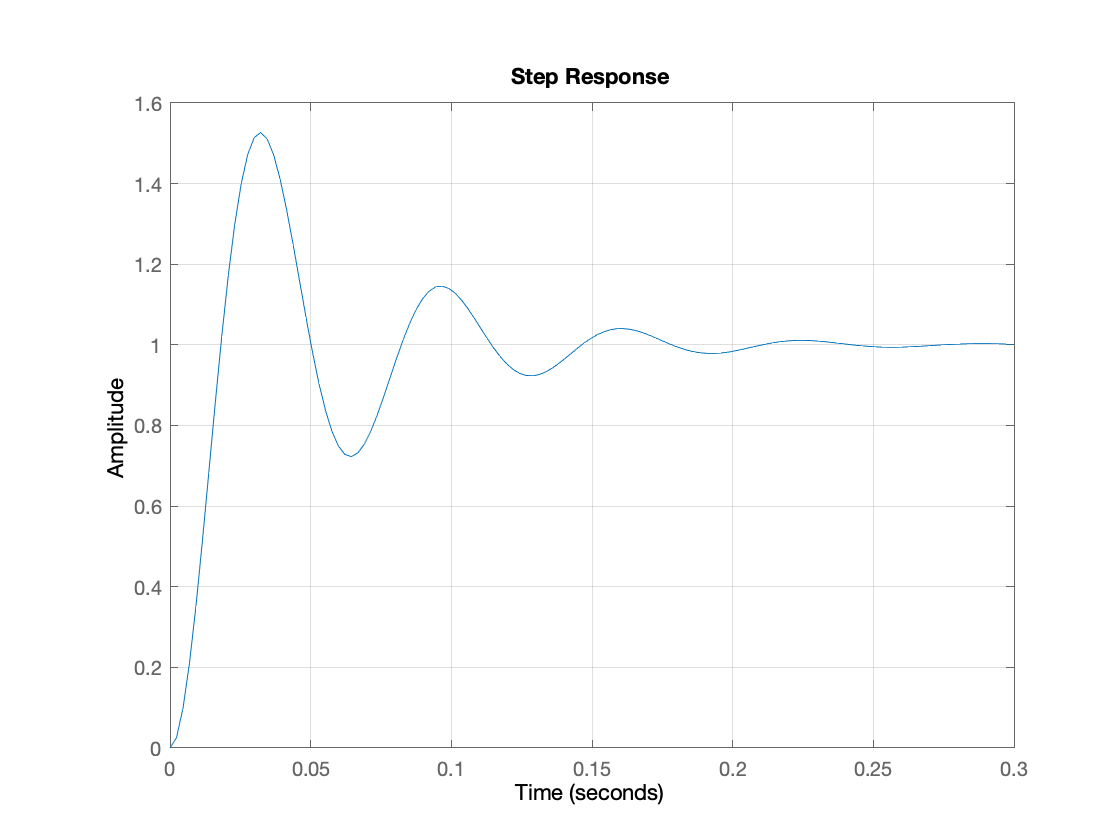


figure(3)
step(T); grid on;


disp(repmat('=',1,80));